# Single Sine Excitation of a Nonlinear Activation Unit: Arbitrary Gain Signals

# Simplifying the Mu Function

Mauro J. Sanchirico III

## Setup

clc; clear; close all;

## Problem

A nonlinear activation unit with input gain $\gamma \text{\,}$ is defined:


$$\varphi \left(v\right)=tanh\left(\gamma \text{\,}v\right)$$


For input signal $v=sin\left(\omega t+\phi \text{\,}\right)$ we wish to know the Fourier Series of the output signal $y=\varphi \left(v\right)$

That is we want to know the Fourier Series of:


$$y\left(t\right)=tanh\left(\gamma \text{\,}sin\left(\omega t+\phi \text{\,}\right)\right)$$


When the input gain is restricted to $|\gamma |<\frac{\pi }{2}$, the following expression can be derived via straightforward Taylor series expansion, the power reduction formula for trigonometric polynomials, and series manipulations:


$$y\left(x\right)=\sum_{n=1}^{\infty } \sum_{m=n}^{\infty } \frac{{\left(-1\right)}^{2m-n-1} 4\left(2^{2m} -1\right){{\gamma \text{\,}}^{2m-1} C}_{m-n}^{2m-1} B_{2m} }{\left(2m\right)!}\sin \left(\left(2n-1\right)x\right)$$


Now we desire an expression for the Fourier Series of $y\left(t\right)$ for all $\gamma >0$.

Such an expression is given:


$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty \;} \frac{{\left(-1\right)}^{m+l} 2^{l+1} m^l }{l!}\gamma^l \int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\sin^l \left(x\right)\textrm{dx}\right\rbrace \sin \left(\left(2n-1\right)\;x\right)$$


This expression contains a special function:


$$\mu \;\left(n,l\right)=\int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\sin^l \left(x\right)\textrm{dx}$$


We wish to break down and simplify this special function.

## Breaking up the inner sum

We can break up the inner sum into even and odd sums.  We use a shorthand for the quotient inside the $l$ summation.


$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty \;} q\left(m,l\right){\;\mu \;\left(n,l\right)\;\gamma }^l \right\rbrace \sin \left(\left(2n-1\right)\;x\right)$$



$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \left(\sum_{l=0}^{\infty \;} q\left(m,2l\right){\;\mu \;\left(n,2l\right)\;\gamma }^{2l} +\sum_{l=0}^{\infty \;} q\left(m,2l+1\right){\;\mu \;\left(n,2l+1\right)\;\gamma }^{2l+1} \right)\right\rbrace \sin \left(\left(2n-1\right)\;x\right)$$


## The even mu function

Here we break up the even mu function by applying a power reduction formula.


$$\mu \;\left(n,2l\right)=\int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\sin^{2l} \left(x\right)\textrm{dx}$$


Expanding $\sin^{2l} \left(x\right)$ using rule 1.320.1 on page 31 of Gradsteyn and Rhyzik (pg 31 - page 80 in the PDF):


$${\mathrm{sin}}^{2l} \left(x\right)=\frac{1}{2^{2l} }\left\lbrace \sum_{k=0}^{l-1} {\left(-1\right)}^{l-k} \;2\;C_k^{2l} \;\mathrm{cos}\left(2\left(l-k\right)x\right)+C_l^{2l} \right\rbrace$$



$$\mu \;\left(n,2l\right)=\int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\frac{1}{2^{2l} }\left\lbrace \sum_{k=0}^{l-1} {\left(-1\right)}^{l-k} \;2\;C_k^{2l} \;\mathrm{cos}\left(2\left(l-k\right)x\right)+C_l^{2l} \right\rbrace \textrm{dx}$$



$$\mu \;\left(n,2l\right)=\frac{1}{2^{2l} }\int_0^{\pi \;} \left\lbrace \sum_{k=0}^{l-1} {\left(-1\right)}^{l-k} \;2\;C_k^{2l} \;\sin \left(\left(2n-1\right)\;x\right)\cos \left(2\left(l-k\right)x\right)+C_l^{2l} \;\sin \left(\left(2n-1\right)\;x\right)\right\rbrace \textrm{dx}$$



$$\mu \;\left(n,2l\right)=\frac{1}{2^{2l} }\sum_{k=0}^{l-1} \;\int_0^{\pi \;} {\left(-1\right)}^{l-k} \;2\;C_k^{2l} \;\sin \left(\left(2n-1\right)\;x\right)\cos \left(2\left(l-k\right)x\right)\mathrm{dx}+\frac{1}{2^{2l} }\int_0^{\pi \;} C_l^{2l} \;\sin \left(\left(2n-1\right)\;x\right)\textrm{dx}$$


***Lemma 1***

=============================================================================


$$\mu \;\left(n,2l\right)=\frac{1}{2^{2l} }\sum_{k=0}^{l-1} \;{\left(-1\right)}^{l-k} \;2\;C_k^{2l} \int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\cos \left(2\left(l-k\right)x\right)\textrm{dx}+\frac{1}{2^{2l} }C_l^{2l} \int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\textrm{dx}$$


=============================================================================

% Code to verify lemma 1
% mu_lemma should equal mu truth for all n and l in the integers

n = 11;
l = 6;

x = 0:0.01:pi;
truth_integrand = sin((2*n-1)*x).*(sin(x)).^(2*l);
mu_truth = trapz(x,truth_integrand);

integrand2 = sin((2*n-1)*x);
integral2 = trapz(x, integrand2);
mu_lemma = (1/2^(2*l))*nchoosek(2*l,l)*integral2;

for k=0:l-1
    integrand1 = sin((2*n-1)*x).*cos(2*(l-k)*x);
    integral1 = trapz(x,integrand1);
    mu_lemma = mu_lemma + (1/2^(2*l))*(-1)^(l-k)*2*nchoosek(2*l,k)*integral1;
end

mu_truth

mu_truth = 1.5884e-08

mu_lemma

mu_lemma = 1.5884e-08

## Solving the Integrals

Now each of the two remaining integrals can be solved trivally:


$$\int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\cos \left(2\left(l-k\right)x\right)\textrm{dx}=\frac{2\left(2n-1\right)}{4n^2 -4n+1-4l^2 +8\;l\;k-4k^2 }$$



$$\int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\textrm{dx}=\frac{2}{2n-1}$$


Substituing these solutions into the formula for $\mu \;\left(n,2l\right)$:


$$\mu \;\left(n,2l\right)=\frac{1}{2^{2l} }\sum_{k=0}^{l-1} \;{\left(-1\right)}^{l-k} \;2\;C_k^{2l} \int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\cos \left(2\left(l-k\right)x\right)\textrm{dx}+\frac{1}{2^{2l} }C_l^{2l} \int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\textrm{dx}$$



$$\mu \;\left(n,2l\right)=\frac{1}{2^{2l} }\sum_{k=0}^{l-1} \;{\left(-1\right)}^{l-k} \;2\;C_k^{2l} \left(\frac{2\left(2n-1\right)}{4n^2 -4n+1-4l^2 +8\;l\;k-4k^2 }\right)+\frac{1}{2^{2l} }C_l^{2l} \left(\frac{2}{2n-1}\right)$$



$$\mu \;\left(n,2l\right)=\sum_{k=0}^{l-1} \frac{{\left(-1\right)}^{l-k} }{2^{2l-2} }\left(\frac{2n-1}{4n^2 -4n+1-4l^2 +8\;l\;k-4k^2 }\right)C_k^{2l} +\frac{1}{2^{2l-1} }\left(\frac{1}{2n-1}\right)C_l^{2l}$$


We can validate these solutions by replacing the calls to trapz in the verification code with the new integration formulas.

% Code to verify lemma 1 with integration rules
% mu_lemma should equal mu truth for all n and l in the integers
% Note that large n or l requires evaluating the integral with a very
% small step size.  When the integration formulas are used, this
% source of error disappears.

n = 4;
l = 5;

x = 0:0.001:pi;
truth_integrand = sin((2*n-1)*x).*(sin(x)).^(2*l);
mu_truth = trapz(x,truth_integrand);

mu_lemma = (1/2^(2*l-1))*nchoosek(2*l,l)*1/(2*n-1);

for k=0:l-1
    term1 = (-1)^(l-k)/2^(2*l-2);
    term2 = (2*n-1)/(4*n^2-4*n+1-4*l^2+8*l*k-4*k^2);
    mu_lemma = mu_lemma + term1*term2*nchoosek(2*l,k);
end

mu_truth

mu_truth = -0.0702

mu_lemma

mu_lemma = -0.0702

Thus we have theorem 1:

***Theorem 1***

===================================================================


$$\mu \;\left(n,2l\right)=\sum_{k=0}^{l-1} \frac{{\left(-1\right)}^{l-k} }{2^{2l-2} }\left(\frac{2n-1}{4n^2 -4n+1-4l^2 +8\;l\;k-4k^2 }\right)C_k^{2l} +\frac{1}{2^{2l-1} }\left(\frac{1}{2n-1}\right)C_l^{2l}$$


===================================================================

## The odd mu function

Here we break up the even mu function by applying a power reduction formula.


$$\mu \;\left(n,2l+1\right)=\int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\sin^{2l+1} \left(x\right)\textrm{dx}$$


A reduction formula for $\sin^{2l^{\prime } -1} \left(x\right)$ is given in rule 1.320.3 on page 31 of Gradsteyn and Rhyzik (page 80 in the PDF):


$${\mathrm{sin}}^{2l^{\prime } -1} \left(x\right)=\frac{1}{2^{2l^{\prime } -2} }\sum_{k=0}^{l^{\prime } -1} {\left(-1\right)}^{l^{\prime } +k-1} C_k^{2l^{\prime } -1} \mathrm{sin}\left(\left(2l^{\prime } -2k-1\right)x\right)$$


Now apply a change of variables:


$$2l^{\prime } -1=2l+1$$



$$l^{\prime } =l+1$$


Then the new rule becomes:


$${\mathrm{sin}}^{2l+1} \left(x\right)=\frac{1}{2^{2l} }\sum_{k=0}^l {\left(-1\right)}^{l+k} C_k^{2l+1} \mathrm{sin}\left(\left(2l-2k+1\right)x\right)$$


We can test this rule in code:

x=0:0.1:pi;

l = 5;
y_truth = sin(x).^(2*l + 1);
y_rule = 0;

for k=0:l
    y_rule = y_rule + (1/2^(2*l))*(-1)^(l+k)*nchoosek(2*l+1, k).*sin((2*l-2*k+1).*x);
end

mean(y_rule - y_truth)

ans = 3.7358e-17

Substituting the power reduction rule into the odd mu function:


$$\mu \;\left(n,2l+1\right)=\int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\left\lbrace \frac{1}{2^{2l} }\sum_{k=0}^l {\left(-1\right)}^{l+k} C_k^{2l+1} \mathrm{sin}\left(\left(2l-2k+1\right)x\right)\right\rbrace \textrm{dx}$$



$$\mu \;\left(n,2l+1\right)=\int_0^{\pi \;} \sum_{k=0}^l \frac{1}{2^{2l} }{\left(-1\right)}^{l+k} C_k^{2l+1} \sin \left(\left(2n-1\right)\;x\right)\sin \left(\left(2l-2k+1\right)x\right)\textrm{dx}$$



$$\mu \;\left(n,2l+1\right)=\sum_{k=0}^l \int_0^{\pi \;} \frac{1}{2^{2l} }{\left(-1\right)}^{l+k} C_k^{2l+1} \sin \left(\left(2n-1\right)\;x\right)\sin \left(\left(2l-2k+1\right)x\right)\textrm{dx}$$



$$\mu \;\left(n,2l+1\right)=\sum_{k=0}^l \frac{1}{2^{2l} }{\left(-1\right)}^{l+k} C_k^{2l+1} \int_0^{\pi \;} \sin \left(\left(2n-1\right)\;x\right)\sin \left(\left(2l-2k+1\right)x\right)\textrm{dx}$$


Evaluating the remaining integral tivially shows that it is equal to zero for all integer $n,l,k$.

Therefor the odd part of the mu function goes to zero:

***Lemma 2***

======================================


$$\mu \;\left(n,2l+1\right)=0$$


======================================

We can verify this algorithmically

l = 10;
k = 5;
n = 5;
x = 0:0.00001:pi;
integrand = sin((2*n-1)*x).*sin((2*l-2*k+1)*x);
integral = trapz(x,integrand)

integral = -4.7104e-15

## Returning to the Expression for $\mathrm{tanh}\left(\gamma \;\mathrm{sin}\left(x\right)\right)$


$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \left(\sum_{l=0}^{\infty \;} q\left(m,2l\right){\;\mu \;\left(n,2l\right)\;\gamma }^{2l} +\sum_{l=0}^{\infty \;} q\left(m,2l+1\right){\;\mu \;\left(n,2l+1\right)\;\gamma }^{2l+1} \right)\right\rbrace \sin \left(\left(2n-1\right)\;x\right)$$


Now apply Lemma 2


$$\mu \;\left(n,2l+1\right)=0$$



$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } \left\lbrace \frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty \;} q\left(m,2l\right){\;\mu \;\left(n,2l\right)\;\gamma }^{2l} \right\rbrace \sin \left(\left(2n-1\right)\;x\right)$$



$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } b_n \;\sin \left(\left(2n-1\right)\;x\right)$$



$$b_n =\frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty \;} q\left(m,2l\right){\;\mu \;\left(n,2l\right)\;\gamma }^{2l}$$


Thus $\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)$ can be fully expanded in terms of $\gamma \;$ as:

***Theorem 2***

====================================================================


$$\textrm{tanh}\left(\gamma \;\sin \left(x\right)\right)=\frac{2}{\pi \;}\sum_{n=1}^{\infty } b_n \;\sin \left(\left(2n-1\right)\;x\right)$$



$$b_n =\frac{2}{2n-1}+\sum_{m=1}^{\infty } \sum_{l=0}^{\infty \;} q\left(m,2l\right){\;\mu \;\left(n,2l\right)\;\gamma }^{2l}$$



$$\mu \;\left(n,2l\right)=\sum_{k=0}^{l-1} {{\left(-1\right)}^{l-k} {\;2}^{-2l+2} \;r\left(n,l,k\right)\;C}_k^{2l} +\frac{2^{-2l+1} }{2n-1}C_l^{2l}$$



$$r\left(n,l,k\right)=\frac{2n-1}{4n^2 -4n+1-4l^2 +8\;l\;k-4k^2 }$$



$$q\left(m,2l\right)=\frac{{\left(-1\right)}^{m+2l} {\;2}^{2l+1} \;m^{2l} }{\left(2l\right)!}$$


====================================================================

We can test this theorem algorithmically:

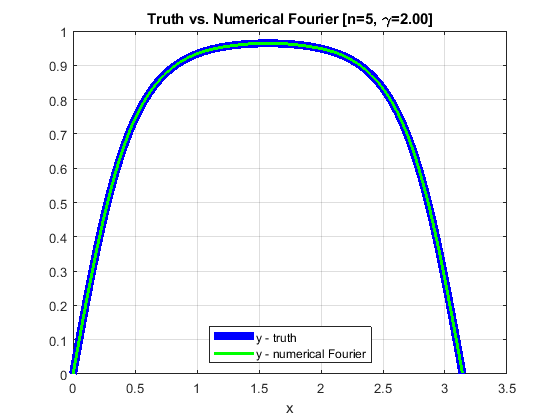

x=0:0.0001:pi;
gamma = 2;
y = tanh(gamma*sin(x));
n_max = 5;

% Compute the b coefs using the definition of the Fourier Series
for n = 1:n_max
    fourier_integrand = y.*sin((2*n-1)*x);
    fourier_integral = trapz(x, fourier_integrand);
    b_numerical(n) = fourier_integral;
end

y_fourier_definition = 0;

for n = 1:n_max
    y_fourier_definition = ...
        y_fourier_definition + 2/pi*b_numerical(n)*sin((2*n-1)*x);
end

% Compute the b coefs using the theorem
% TODO

figure;
plot(x,y, 'linewidth', 6, 'Color', 'b');
hold on;
plot(x,y_fourier_definition, 'linewidth', 2, 'Color', 'g');
grid on;
legend('y - truth', 'y - numerical Fourier', 'location', 'south');
xlabel('x');
title_str = sprintf('Truth vs. Numerical Fourier [n=%i, \\gamma=%0.2f]', n, gamma);
title(title_str);